# MATLAB Olympiade 2022 

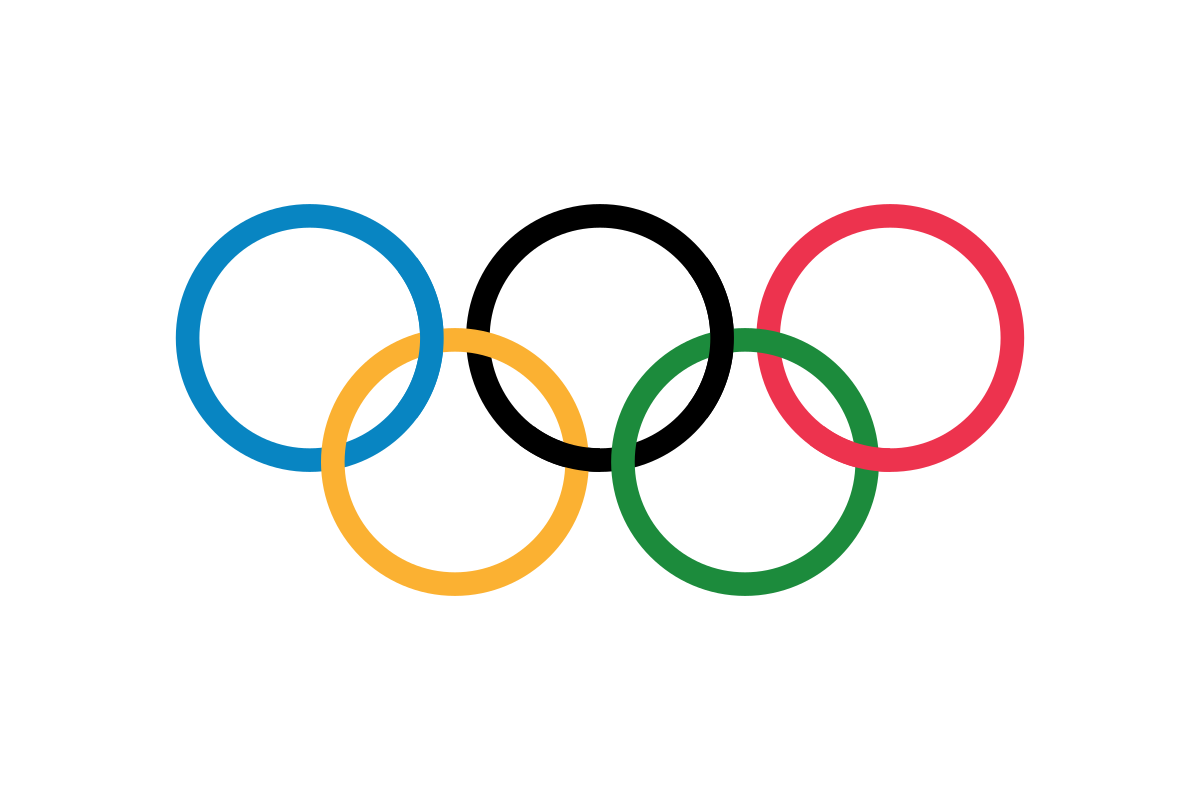

Willkommen zur MATLAB-Olympiade! 

Dieses Skript fasst alle Aufgaben zusammen. Bearbeitet die Aufgaben bitte in den jeweiligen Funktionsdatein (z.B. gruppenalter.m) . Wenn ihr mit einer Aufgabe fertig seid, könnt ihr in dieses Skript zurückkehren und entweder das ganze Skript ausführen ("Run", grüner Pfeil) oder nur den jeweiligen Abschnitt der Aufgabe einzeln ausführen ("Run Section", Symbol neben "Run").

Im letzten Abschnitt ist ein simpler Aufgaben-Checker, der prüft, ob die Funktionen auch das richtige zurückgeben . Der Aufgaben-Checker prüft dagegen nicht, wie ihr die Funktionen implementiert habt. Wenn ihr das ganze Skript oder eben nur den letzten Abschnitt ausführt (oder nur die Funktion `funktionscheck()` im Command Window aufruft), seht ihr das richtig/falsch-Ergebnis für jede Aufgabe (mit Ausnahme der Aufgabe 8).

clear % Variablen im Workspace löschen
clc % Command Window sauber machen

## 1) Durchschnittliches Gruppenalter

a) Schreibt eine Funktion, die das Durchschnittsalter eurer Gruppe ausgibt. Tragt hier das Alter von jedem Gruppenmitglied ein:

vektor_alter = [19, 24, 18];
% vektor_alter = [];
durchschnittsalter = gruppenalter(vektor_alter)

durchschnittsalter = 20.3333

## 2) Roll the Dice

Schreibt eine Funktion, die einen Wurf von n Würfeln mit x Seiten (Augenzahl 1 bis x) abbildet und die Summe der Augen zurückgibt.

Tipp: recherchiert, welche Möglichkeiten MATLAB bietet, Zufallszahlen zu erzeugen. (nutze z.B. die randi() funktion)

AnzahlWuerfel = 4;
AnzahlSeiten = 10;
Augensumme = rollTheDice(AnzahlWuerfel,AnzahlSeiten)

Augensumme = 15

## 3) "Einführung" in die technische Mechanik

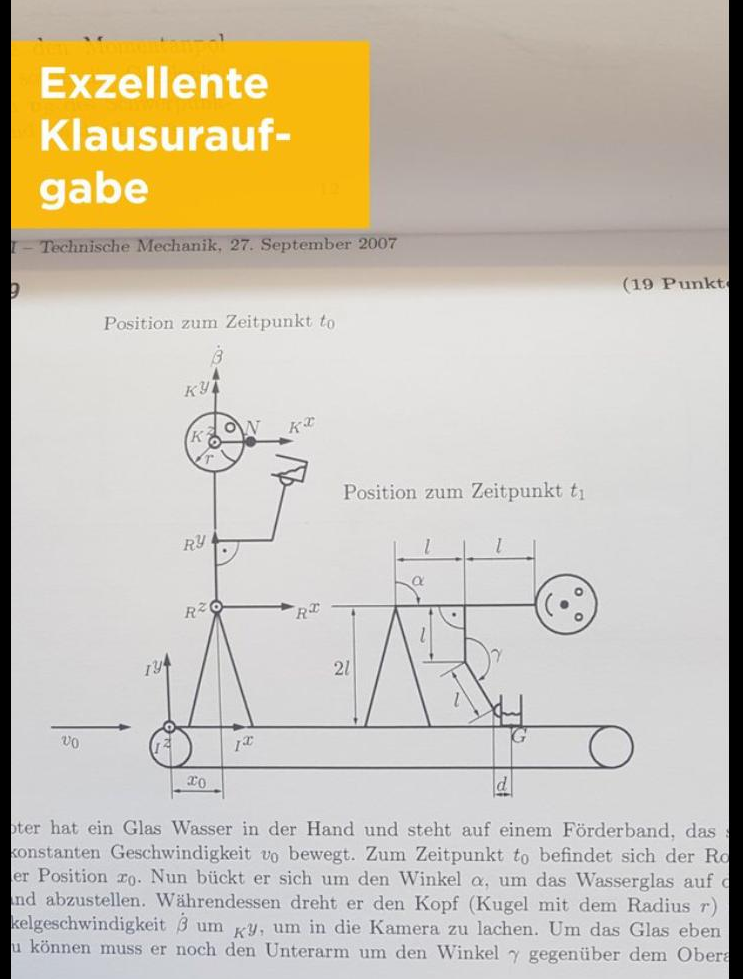

Moment =  Hebelarm x Kraft

"Der Momentenvektor um einen Bezugspunkt ist das Kreuzprodukt aus dem Positionsvektor des Angriffspunktes der Kraft (bzgl des Bezugspunkts) und dem Kraftvektor"

Berechnet den Momentenvektor. 

kraft = [1;2;3];
hebelarm = [1;4;1];

moment = momentenberechnung(kraft, hebelarm)

moment =     10
    -2
    -2


## 4) Primzahlerkennung

Schreibt eine Funktion die angibt ob ein input eine Primzahl ist.

- der input `testzahl` soll eine beliebige Zahl >= 3 sein

- der output `istprimzahl` gibt an ob der input eine Primzahl ist. ja -> `istprimzahl = 1`, nein -> `istprimzahl = 0`

Tipp: Das Residuum einer ganzzahligen Division erhält man mit der Modulo-Funktion

testzahl = 7; 
istprimzahl = PrimzahlCheck(testzahl)

istprimzahl = 1

## 5) Taylor Reihe

Nach 30 Jahren engagierter Arbeit als CEO hat dich TI in eine Unterabteilung im Himalaya versetzt. Deine Aufgabe als Leiter der Unterabteilung ist es, die transzendentalen Funktionen auf den Himalaya-Computern zu implementieren. Du beschließt, mit einer Exponentialfunktion anzufangen, also findest du die folgende Taylorreihen-Approximation, um eine dieser Funktionen darzustellen:

Da die Computer im Himalaya jedoch extrem langsam sind (möglicherweise aufgrund der großen Höhe), musst du die Taylor-Reihe so effizient wie möglich einsetzen. Mit anderen Worten: Du musst also die kleinstmögliche Anzahl von Termen verwenden, um deinen Fehler von 0,001 nicht zu überschreiten. Du nimmst x = 3 als Wert, bei dem du die Funktion auswertest. Berechne und zeige die Anzahl der Terme an, die notwendig sind, damit die Funktion innerhalb des zulässigen Fehlers liegt.

requiredTerms = taylorseries(3)

requiredTerms = 13

## 6) Weltmeisterschaft

Die Weltmeisterschaft steht vor der Tür und alle wollen wissen, wer einen weiteren Stern auf dem Trikot bekommt! Wird Deutschland zum fünften Mal Weltmeister?  Um die Angst zu verringern, haben wir ein Skript erstellt, das das Ergebnis jedes Spiels der K.O.-Phase simuliert, aber wir müssen immer noch wissen, welche Mannschaften die Gruppenphase überstehen werden. 

In der Gruppenphase ziehen die beiden besten Teams jeder Gruppe in die nächste Phase ein. Um diesen Prozess zu vereinfachen, wählen wir zufällig zwei Mannschaften aus. Bearbeit die weltmeristerschaft.m so, dass ein kompletter Turnierablauf simuliert wird bei dem die Gewinner jeweils zufällig ausgelost werden. Der Weltmeister und die Halbfinalisten sollen ausgegeben werden.

[weltmeister, semifinals] = weltmeisterschaft

weltmeister = 1×1 cell array
    {'Schweiz'}


semifinals = 4×1 cell array
    {'Iran'    }
    {'Südkorea'}
    {'USA'     }
    {'Schweiz' }


## 7) Monte Carlo

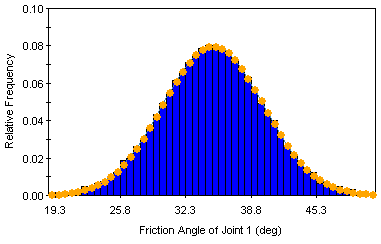

Eine Normalverteilung wird über den Mittelwert und die Varianz (bzw. Standardabweichung) definiert. Erstellt in der Funktion MonteCarlo für vorgegebenen Mittelwert und Varianz eine Normalverteilung. Erstellt dann einen Vektor aus Zufallsvariablen, die der erstellten Wahrscheinlichkeitsverteilung folgen und berechnet mit MATLAB-Funktionen umgekehrt aus diesem Vektor wieder den Mittelwert und die Varianz. Mehr Hinweise findet ihr in der Funktion `MonteCarlo`.

Mittelwert = 10;
Varianz = 2;
[Mittelwert_approx,Varianz_approx] = MonteCarlo(Mittelwert,Varianz)

Mittelwert_approx = 10.0096

Varianz_approx = 2.0216

## 8) Vier Plots

Lasst uns ein bisschen Reverse Engineering machen! Erstelle Vektoren x und y, die, wenn sie aufgetragen und verbunden werden, das Muster in Abbildung (a)-(d) zeigen.

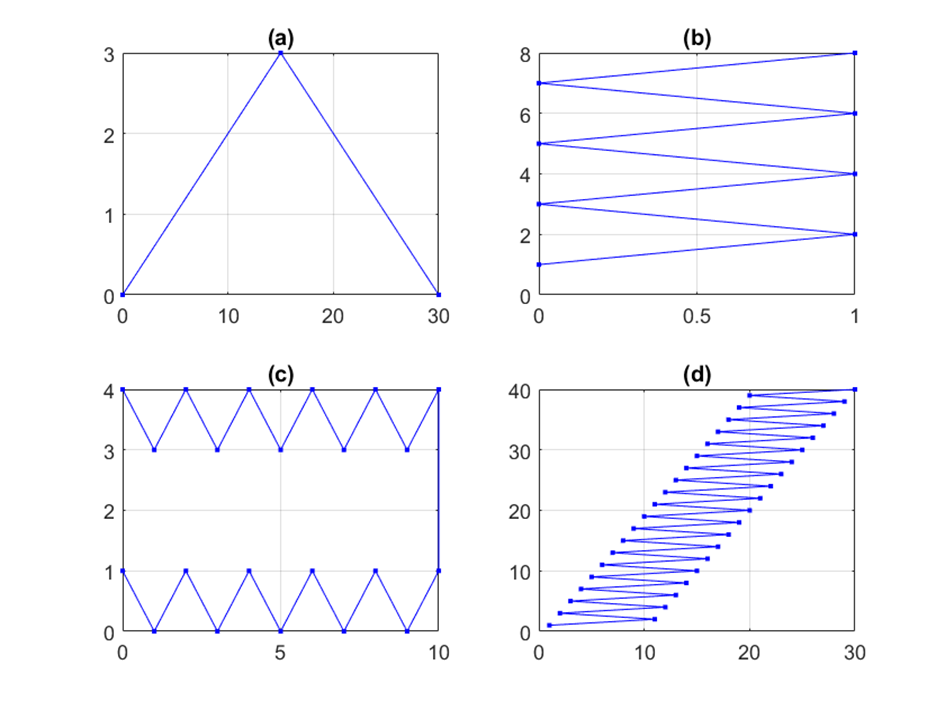

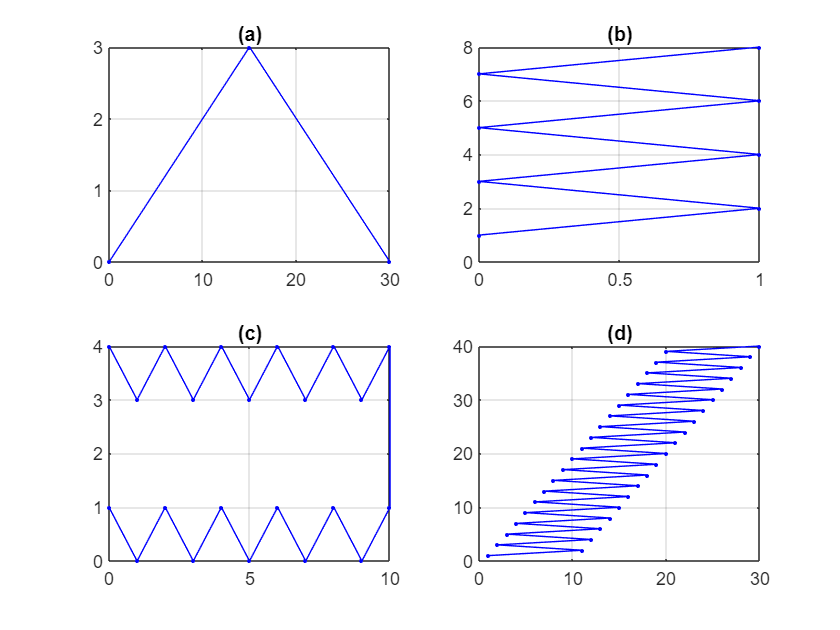

vierplots()

## 9) Object Detection (Hausaufgabe -> zählt nicht für die Olympiade)

Jetzt wird's interaktiver: In dieser Aufgabe nutzt ihr euer Smartphone und ein vortrainiertes künstliches neuronales Netzwerk, um Objekte zu klassifizieren. Diese Aufgabe ist nur als Spielerei gedacht. Eventuell funktioniert das Programm auch nicht bei jedem. Probiert es einfach mal aus! Seid nicht all zu sehr überrascht, wenn eine Gabel als Pfannenwender erkannt wird :D

- Im Ordner der Olympiade befindet sich auch der Ordner "ObjectDetection"

- Loggt euch im Browser in MATLAB-Drive [drive.matlab.com](https://drive.matlab.com) (die Cloud von Mathworks) oder MATLAB-Online [matlab.mathworks.com](https://matlab.mathworks.com/) ein (mit eurer eigenen MATLAB-Account ab12xyz@matlab.rbg.tum.de) und ladet dort den Ordner ObjectDetection hoh

- Ladet aus dem App/Play-Store die "MATLAB Mobile" App

- Loggt euch mit eurem MATLAB-Account ein

- Im Menü unter "Sensors" > "More": aktiviert "Sensor Access" und "Camera Access"

- In der MATLAB Mobile App seht ihr diesen Ordner nun im Menü unter "Files". Geht in den Ordner und öffnet das Skript "detectObject"

- Führt das Skript aus, indem ihr oben auf das Dreieck tippt. 

- Ihr seht dann eine Kamera-Oberfläche: Macht ein Foto von den unten geforderten Objekten. 

- Das Skript gibt dann aus, welches Objekt erkannt wurde. Gleichzeitig gibt das Skript noch einen Teil des Schlüsselworts aus, falls es sich um eines der geforderten Objekte handelt

- Um ein weiteres Objekt zu erkennen, startet einfach das Skript neu

Schreibt die Schlüsselwörter von den folgenden Objekten in der selben Reihenfolge ohne Leerzeichen zusammen:

- Kugelschreiber

- Tasse

- Schuh

- Flasche

keyword = 'MerryLockd0wn';

## Ergebnis 

functionCheck()

	1) gruppenalter :		correct
	2) rollTheDice:			correct
	3) momentenberechnung:		correct
	4) PrimzahlCheck:		correct
	5) taylorseries:		correct
	6) Weltmeisterschaft:		correct
	7) MonteCarlo:			correct
	8) Vier Plots: 			richtig NUR WENN plots identisch aussehen 
	9) ObjectDetection:		correct
